**For loop**

for j=1:5              % use for-loops to execute iterations / repetitions
    for i=1:3
         a(i, j) = i + j-1;
    end
end

***if*****  Conditional **

a = zeros(3);  b = zeros(3); 
for j=1:3 
   for i=1:3 
      a(i,j) = rand;         % use rand to generate a random number 
      if a(i,j) > 0.5 
         b(i,j) = 1; 
      end 
  end 
end

Equivalent vector operations  . . .

A = rand(3);      % A is a 3x3 random number double array
B = zeros(3);      % Initialize B as a 3x3 array of zeroes
B(A > 0.5) = 1;   % set to 1 all elements of B for which A > 0.5

Another quivalent vector operation . . .

% A = rand(3);      % A is a 3x3 random number double array
B = (A > 0.5);      % Initialize B and set to 1 all elements of B for which A > 0.5


**Cell array**

A cell array is a special array of arrays. Each element of the cell array  may point to a scalar,  an array, or another cell array.

C = cell(2, 3);   % create 2x3 empty cell array 
M = magic(2);
a = 1:3; b = [4;5;6]; s = 'This is a string.';
C{1,1} = M; C{1,2} = a; C{2,1} = b; C{2,2} = s; C{1,3} = {1};

**Line Plot**

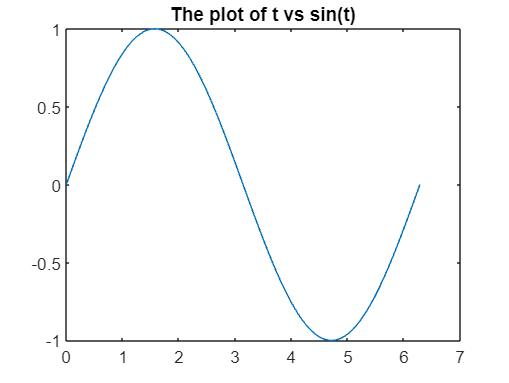

t = 0:pi/100:2*pi;
y = sin(t);
plot(t,y);
title('The plot of t vs sin(t)');

**Multiple line plots**

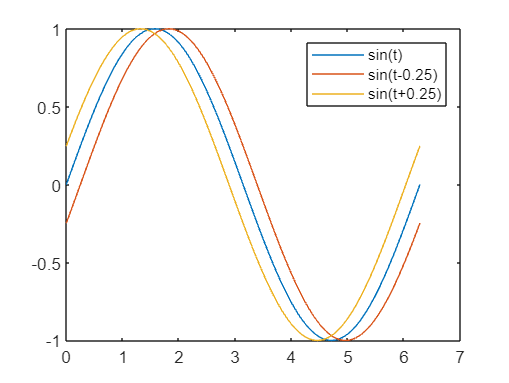

y2 = sin(t-0.25); 
y3 = sin(t+0.25); 
plot(t,y,t,y2,t,y3)   % make 2D line plot of 3 curves 
legend('sin(t)','sin(t-0.25)','sin(t+0.25)') ;

**Bar diagram**

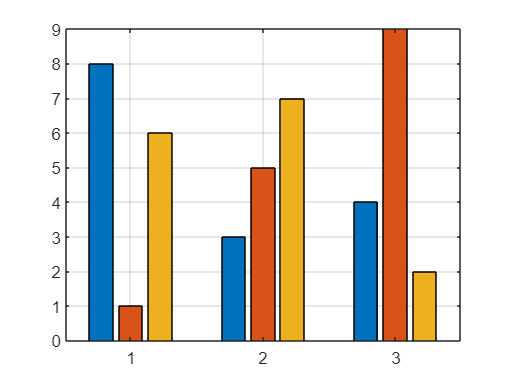

x = magic(3);    % generate data for bar graph
bar(x)               % create bar chart
grid                  % add grid 

**2D Bar diagram**

x = magic(3);    % generate data for bar graph
bar(x)               % create bar chart
grid                  % add grid for clarity

**Surface plot**

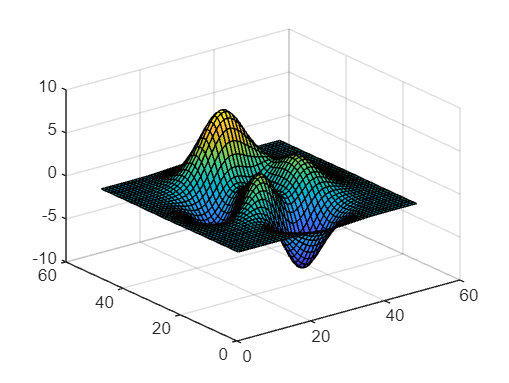

Z = peaks;    % generate data for plot;   peaks returns  function values
surf(Z);         % surface plot of Z

% shading flat 

**Contour Plots**

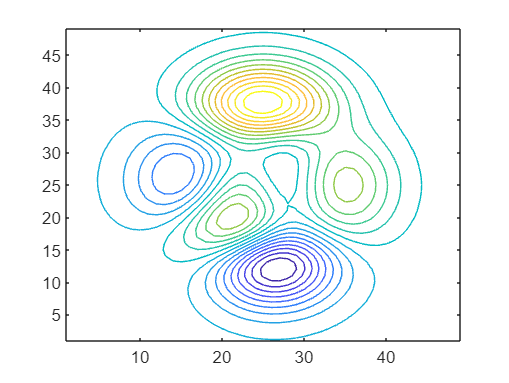

Z = peaks;
contour(Z, 20)    % contour plot of Z with 20 contours

**Integration  Example — using for-loop**

- Integration of cosine from 0 to π/2.

- Use mid-point rule for simplicity

tic
   m = 100;
   a = 0;               % lower limit of integration
   b = pi/2;            % upper limit of integration
   h = (b - a)/m;       % increment length
   integral = 0;        % initialize integral
   for i=1:m
     x = a+(i-0.5)*h;   % mid-point of increment i
     integral = integral + cos(x)*h;
   end
toc

Elapsed time is 0.007034 seconds.


**Integration  Example — using vector form**

% integration with vector form
tic
   m = 100;
   a = 0;               % lower limit of integration
   b = pi/2;            % upper limit of integration
   h = (b - a)/m;       % increment length
   x = a+h/2:h:b-h/2;   % mid-point of m increments
   integral = sum(cos(x))*h;
toc

Elapsed time is 0.006404 seconds.


**Hands On Exercise**

1. Use the editor to write a program to generate the figure that describe the integration scheme we discussed. (Hint: use *plot*  to plot the cosine curve. Use *bar  *to draw the rectangles that depict the integrated value for each interval. Save as plotIntegral.m

Compute the integrals using 10 different  increment sizes (h), for *m=10, 20, 30, . . . , 100*. Plot these *10* values  to see how the solution converges to the analytical value of *1*. 

a = 0;  b=pi/2;                 % lower  and upper limits of integration
m = 8;                             % number of increments
h = (b-a)/m;                    % increment size
x= a+h/2:h:b-h/2;            % m mid-points
bh = bar(x,cos(x),1,'c');   % make bar chart with the bars in cyan
hold                                 % all plots will be superposed on same figure

Current plot held


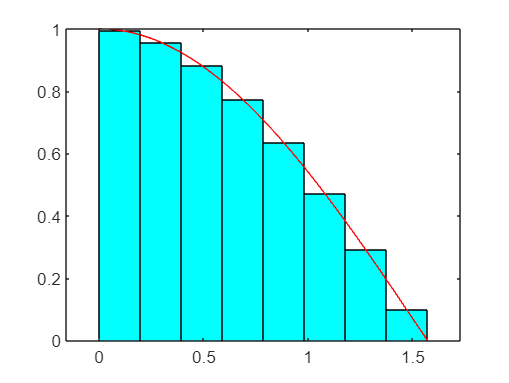

x = a:h/10:b;                    % use more points at which to evaluate cosine
f = cos(x);                        % compute cosine at x
ph = plot(x,f,'r');               % plots x vs f, in red

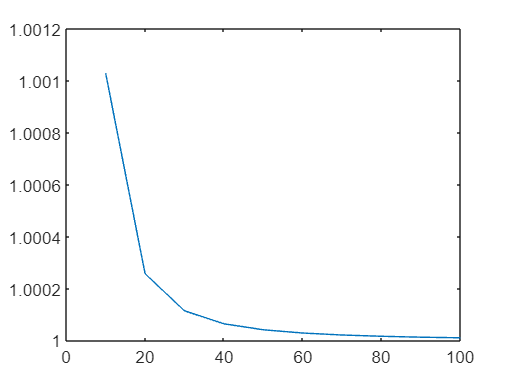

% Compute integral with different values of m to study convergence
for i=1:10
    n(i) = 10+(i-1)*10;
    h = (b-a)/n(i);
    x = a+h/2:h:b-h/2;
    integral(i) = sum(cos(x)*h);
end
figure   % create a new figure
plot(n, integral)